5/18/2025  Develop a function to find the height/cutoff of a cluster in a hierarchical clustering tree

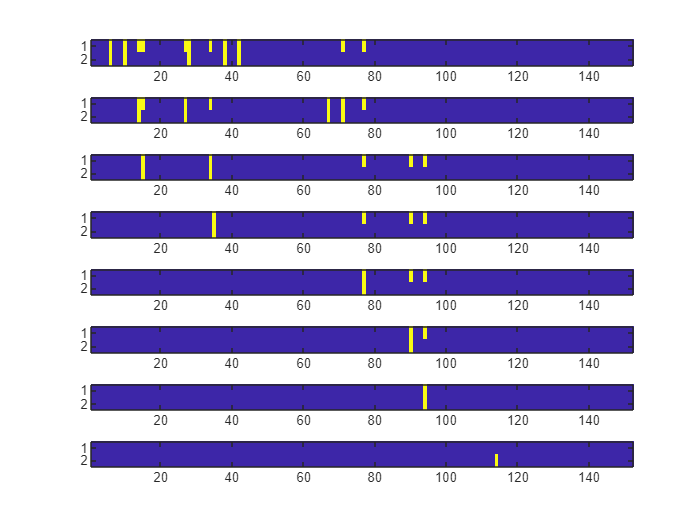

     6    10    28    38    42

    14    27    67    71

    15    34

    35

    77

    90

    94



    0.3549



nodeInd = linkerOrigInd{2}(:);
m = size(tree, 1) + 1;

figure
tiledlayout("vertical");
while true
    M = ismember(tree(:,1:2), nodeInd);
    nexttile;
    imagesc(M')
    lastI = I;
    I = find(sum(M,2) == 2);
    disp(I');
    if isempty(I)
        disp(tree(lastI,3));
        break
        % error("The leaves do not converge on a single node");
    end
    isLinked = ismember(nodeInd, tree(I,:));
    nodeInd = [nodeInd(~isLinked); m+I];
end

5/18/2024  Check the order of units in clusTb between original se and cached data

srcTb = LMV.Data.FindSource([]);
seArray = NP.SE.LoadSession(srcTb.path);


Loading se 1 - NP38_B5

Loading se 2 - NP38_B6

Loading se 3 - NP69_B1

Loading se 4 - NP69_B2

Loading se 5 - NP78_B1

Loading se 6 - NP35_B2

Loading se 7 - NP43_B1

Loading se 8 - NP50_B3

Loading se 9 - NP53_B1

Loading se 10 - NP41_B1

Loading se 11 - NP44_B2

Loading se 12 - NP44_B3

Loading se 13 - NP45_B1

Loading se 14 - NP45_B2

Loading se 15 - NP46_B1

Loading se 16 - NP47_B3

Loading se 17 - NP56_B1

Loading se 18 - NP52_B1

Loading se 19 - NP52_B2

Loading se 20 - NP54_B1


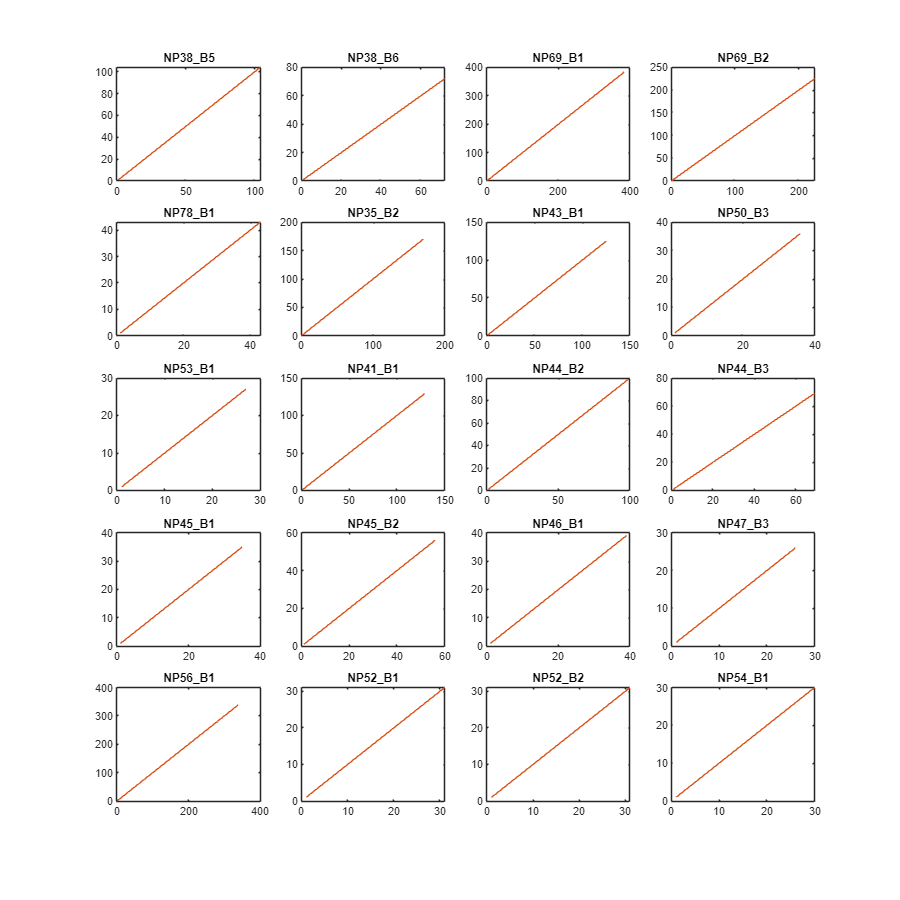

rTest = LMV.Resp.LoadPhaseResponseTest(srcTb.recId);

f = MPlot.Figure(1); clf
f.Position(3:4) = [1000 1000];

for i = 1 : height(srcTb)
    clusTb = NP.Unit.GetClusTb(seArray(i));
    [~, I] = MMath.SortLike(rTest(i).clusTb.clusId, clusTb.clusId);
    
    ax = nexttile;
    plot(I); hold on
    plot(1:numel(I))
    title(srcTb.recId{i}, 'Interpreter', 'none');
end

uid = 3502e5 + [795 829];
uid = 4301e5 + [29 582 584];
uid = 5003e5 + [452 456];

uid = [380500266 380600105 380600177];

uid = 5201e5 + [16 87 94];
uid = [520200153 540100099];


uid = 4101e5 + [155 170 211];
uid = 4101e5 + [224 315 400];
uid = 4101e5 + [416 422 424];
uid = 4101e5 + [450 463];

uid = 4402e5 + [462 479];
uid = 4403e5 + [574 575 594];
uid = 4403e5 + [595 601];
uid = 4501e5 + [4 165 286];
uid = 4501e5 + [298 314 322];
uid = 4502e5 + [52 422 608];

uid = 4601e5 + [0 3 5];
uid = 4601e5 + [13 30 98];
uid = 4601e5 + [128 236 248];
uid = 4601e5 + [250 271];

uid = 4703e5 + [85 99];

uid = 5601e5 + [916 10095 10714];


LMV.Overview.SentencesFromCache(uid, 'StimIdList', LMV.Param.stimIdList14, 'TaskPhase', 'lmv')



4/18/2024  Examine feedback/mirror cross-correlations

recId = "NP44_B3";

seqData = LMV.Mirror.LoadSeqData(recId);
triTb = LMV.Mirror.ComputeSeqPethXC(seqData.triTb);

xcTb = LMV.Mirror.ExtractXC(triTb);
head(xcTb)

k = 6;

uXcTb = xcTb;
uXcTb.spikeTime = cellfun(@(x) x(:,k), xcTb.spikeTime, 'Uni', false);
uXcTb.hh = cellfun(@(x) x(:,k), xcTb.hh, 'Uni', false);
uXcTb.ee = cellfun(@(x) x(:,k), xcTb.ee, 'Uni', false);
uXcTb.stats = cellfun(@(x) x(k,:), xcTb.stats, 'Uni', false);
uXcTb.xrPkVal_feedback = xcTb.xrPkVal_feedback(:,k);
uXcTb.xrPkVal_prod = xcTb.xrPkVal_prod(:,k);


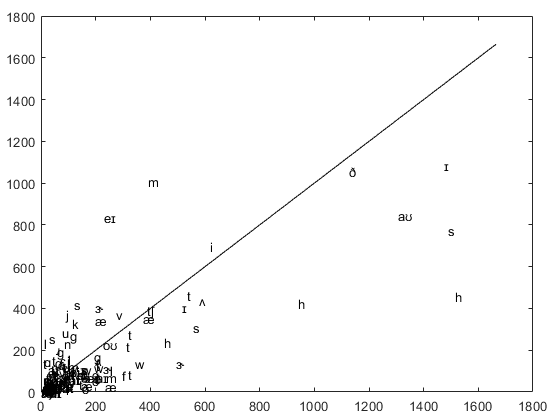


x = uXcTb.xrPkVal_feedback;
y = uXcTb.xrPkVal_prod;
lb = MLing.ARPA2IPA(uXcTb.seed);
m = max([x;y]) * 1.1;

figure(1); clf
tl = tiledlayout("flow");
tl.Padding = "compact";
ax = nexttile;
h = plot(x, y, 'w.');
plot([0 m]', [0 m]', 'Color', [0 0 0 .2]); hold on
text(x, y, lb);


h.UserData.forBrush = true;

Invalid or deleted object.

% h.UserData.seqStr = uXcTb.seqStr;
ax.UserData.seed = uXcTb.seed;
ax.UserData.seqStr = uXcTb.seqStr;
ax.UserData.triTb = triTb;

axis square equal tight
MPlot.Axes(ax);

b = brush(gcf);
b.Enable = 'on';
b.ActionPostCallback = @LMV.Mirror.PlotSeqPethOverlayOnBrush;

% dcm = datacursormode;
% dcm.Enable = 'on';
% dcm.DisplayStyle = 'window';
% dcm.UpdateFcn = @LMV.Mirror.DatatipCallback;


4/8/2024  Test different peak identification in r2 timeseries

Load data

uid = [41010e4+[245 434 155 463], 56011e4+[714], 45020e4+[307], 46010e4+[242 3]];

uData = NP.Unit.LoadUnitCache(uid);
mdls = cellfun(@(x) x.trf.phone_prod, uData)

f = figure;
f.Position(3:4) = [800 800];
for i = 1 : numel(mdls)
    r = mdls(i).r2each;
    dt = mdls(i).dt;

    [rPk, tPk, iPk] = LMV.RF.FindPeakR2(r, dt);

    ax = nexttile;
    findpeaks(r, dt, "MinPeakProminence", 0.01, "Annotate", "extents");
    hold on
    plot(tPk, rPk, 'r*');
    legend off
    ylim([0 .5]);
    title(sprintf("%s, r_{prom} = %.2f", mdls(i).resps, p));
end


4/8/2024  Test L1 regularization on weight distributions

Load data

load("C:\chang_lab\project_np\analysis\trf\ce\NP41_B1_ce.mat");
uid = NP.Unit.ClusId2Ind(NP.Unit.GetBaseClusId(ce)+[245], ce) % 155 450 463

sets = "strf";
phases = "prod";
L = 10.^(-4:3);

tbs = cell(size(L));
for i = 1 : numel(L)
    tbs{i} = LMV.TRF.FitSpeechEncoding(ce, uid, FeatSet=sets, Target=phases, Lambda=L(i), Alpha=1, NBoot=0);
end

for i = 1 : numel(sets)
    PlotWeights(tbs, uid, join([sets(i) phases], "_"));
end


4/7/2024  Test fixed L2 lambdas on example units

Load data

load("C:\chang_lab\project_np\analysis\trf\ce\NP46_B1_ce.mat");
uid = NP.Unit.ClusId2Ind(NP.Unit.GetBaseClusId(ce)+[248 30 5], ce)

Test phone models

sets = ["phone", "strf", "artic"];
phases = "prod";

for i = 1 : numel(sets)
    switch sets(i)
        case 'artic'
            L = 1;
        case 'strf'
            L = 50;
        otherwise
            L = 0;
    end
    clusTb = LMV.RF.FitSlidingTimeRF(ce, uid, FeatSet=sets(i), Target=phases, Lambda=L, NBoot=0);
    ce.clusTb = clusTb;
end

for i = 1 : numel(sets)
    PlotWeights({clusTb}, uid, join([sets(i) phases], "_"));
end

Load data

load("C:\chang_lab\project_np\analysis\trf\ce\NP41_B1_ce.mat");
uid = NP.Unit.ClusId2Ind(NP.Unit.GetBaseClusId(ce)+[245 155 450 463], ce)

sets = ["phone", "strf", "artic"];
phases = "prod";

for i = 1 : numel(sets)
    switch sets(i)
        case 'artic'
            L = 1;
        case 'strf'
            L = 50;
        otherwise
            L = 0;
    end
    clusTb = LMV.RF.FitSlidingTimeRF(ce, uid, FeatSet=sets(i), Target=phases, Lambda=L, NBoot=0);
    ce.clusTb = clusTb;
end

for i = 1 : numel(sets)
    PlotWeights({clusTb}, uid, join([sets(i) phases], "_"));
end

4/7/2024  Test reguarization strength on u245 and u155

Load ce

load("C:\chang_lab\project_np\analysis\trf\ce\NP41_B1_ce.mat");

Get indices of example units

uid = NP.Unit.ClusId2Ind(410100000+[245 155 450 463], ce)

Test STRF

L = 10.^(0:3);
strfTbs = cell(size(L));
for i = 1 : numel(L)
    strfTbs{i} = LMV.TRF.FitSpeechEncoding(ce, uid, FeatSet="strf", Target="prod", Lambda=L(i), NBoot=0);
end

PlotWeights(strfTbs, uid, "strf_prod");

Test artics

L = 10.^(-5:2);
articTbs = cell(size(L));
for i = 1 : numel(L)
    articTbs{i} = LMV.RF.FitSlidingTimeRF(ce, uid(1), FeatSet="artic", Target="prod", Lambda=L(i), NBoot=0);
end

PlotWeights(articTbs, uid(1), "artic_prod");


Test acous

L = 10.^(-4:3);
srfTbs = cell(size(L));
for i = 1 : numel(L)
    srfTbs{i} = LMV.RF.FitSlidingTimeRF(ce, uid(1), FeatSet="strf", Target="prod", Lambda=L(i), NBoot=0);
end

PlotWeights(srfTbs, uid(1), "strf_prod");

4/6/2024  Test reguarization strength on u245

Load ce

load("C:\chang_lab\project_np\analysis\trf\ce\NP41_B1_ce.mat");

Test STRF models

L = 10.^(-4:3);
tbs = cell(size(L));
for i = 1 : numel(L)
    tbs{i} = LMV.TRF.FitSpeechEncoding(ce, 23, FeatSet="strf", Target="prod", Lambda=L(i), NBoot=0);
end

f = figure; clf
f.Position(3:4) = [200*numel(tbs) 500];
tl = tiledlayout(1,numel(tbs));
for i = 1 : numel(tbs)
    ax = nexttile;
    LMV.TRF.PlotWeights2(ax, tbs{i}, 23, "strf_prod");
    MPlot.Axes(ax);
end


Test phoneme model

L = 10.^(-4:3);
tbs2 = cell(size(L));
for i = 1 : numel(L)
    tbs2{i} = LMV.TRF.FitSpeechEncoding(ce, 23, FeatSet="phone", Target="prod", Lambda=L(i), NBoot=0);
end

f = figure; clf
f.Position(3:4) = [200*numel(tbs2) 500];
tl = tiledlayout(1,numel(tbs2));
for i = 1 : numel(tbs2)
    ax = nexttile;
    LMV.TRF.PlotWeights2(ax, tbs2{i}, 23, "phone_prod");
    MPlot.Axes(ax);
end


Test combo4pm model

L = 10.^(-4:3);
tbs3 = cell(size(L));
for i = 1 : numel(L)
    tbs3{i} = LMV.TRF.FitSpeechEncoding(ce, 23, FeatSet="combo4pm", Target="prod", Lambda=L(i), NBoot=0);
end

f = figure; clf
f.Position(3:4) = [200*numel(tbs3) 500];
tl = tiledlayout(1,numel(tbs3));
for i = 1 : numel(tbs3)
    ax = nexttile;
    LMV.TRF.PlotWeights2(ax, tbs3{i}, 23, "combo4pm_prod");
    MPlot.Axes(ax);
end

Test combo3akt model

L = 10.^(-4:3);
tbs4 = cell(size(L));
for i = 1 : numel(L)
    tbs4{i} = LMV.TRF.FitSpeechEncoding(ce, 23, FeatSet="combo3akt", Target="prod", Lambda=L(i), NBoot=0);
end

f = figure; clf
f.Position(3:4) = [200*numel(tbs4) 500];
tl = tiledlayout(1,numel(tbs4));
for i = 1 : numel(tbs4)
    ax = nexttile;
    LMV.TRF.PlotWeights2(ax, tbs4{i}, 23, "combo3akt_prod");
    MPlot.Axes(ax);
end

4/5/2024  Fit phoneme TRF with single time offsets in different models 

Load ce

load("C:\chang_lab\project_np\analysis\trf\ce\NP41_B1_ce.mat");

Fit models

clusTb1 = LMV.RF.FitSlidingTimeRF(ce, 23, FeatSet="phone", Target="prod", Lambda=0);

mdl = clusTb1.phone_prod{23};

figure
plot(-mdl.dt, mdl.r2each);
title("r2");
[~, iPk] = max(mdl.r2each);
dtPk = -mdl.dt(iPk);
disp(dtPk);

Test a better way to getting top peak

findpeaks(flip(mdl.r2each), "Annotate","extents");
[pks,locs,w,p] = findpeaks(mdl.r2each, SortStr="descend")


f = figure; clf
f.Position(3:4) = [200 500];
ax = nexttile;
LMV.TRF.PlotWeights2(ax, clusTb1, 23, "phone_prod");
plot([dtPk dtPk]', ax.YLim, 'k')
MPlot.Axes(ax);

clusTb2 = clusTb1;
mdl = clusTb2.phone_prod{23}.mdls{mdl.r2Idx};
mdl.feats = clusTb2.phone_prod{23}.feats;
clusTb2.phone_prod{23} = mdl;

f = figure; clf
f.Position(3:4) = [800 200];
ax = nexttile;
LMV.RF.PlotWeights(ax, clusTb2, 23, "phone_prod");


3/29/2024  Test wavelet transformation on example units in Signal Analyzer

Load sentence averaged (M1) data

anaDir = fullfile(NP.Data.GetAnalysisRoot, 'sparsity');
ceSearch = MBrowse.Dir2Table(fullfile(anaDir, 'ce_m1_sentence-avg', '*_ce_m1.mat'));
ceArray = NP.CE.LoadSession(fullfile(ceSearch.folder, ceSearch.name));

Select recordings

uid = [410100245 460100005 450100286 450100323 410100450];

uid = [460100128 440300295 460100240 440300246 460100098];

uData = NP.Unit.LoadUnitCache(uid, 'DataSource', 'm1');
se = LMV.SE.UnitCache2SE(uData);

se.userData.expInfo.subjectId = 'NP00';
se.userData.expInfo.blockId = 'B0';
se.userData.recMeta.Region = '';
se.userData.recMeta.Subregion = '';

senTb = se.SplitConditions(["stimId" "stimText"], 'taskValue');
for s = 1 : height(senTb)
    fprintf("\n%s\n", senTb.stimText(s));
    senTb.ce(s) = LMV.SE.ComputeSessionPETH(senTb.se(s));
end
ce = senTb.ce.Merge();
ce.userData = senTb.ce(1).userData;

% Get responses
tv = ce.GetTable('taskValue');
isSen = ismember(tv.stimId, LMV.Param.stimIdList14);
isUnit = ismember(ce.clusTb.clusId, uid);
[t, Y] = ce.GetArray('resp', isSen, find(isUnit)+1);

for i = 1 : size(Y,2)
    disp(uid(i));
    y = Y(:,i);

    fs = 1/diff(t(1:2));
    ys = MNeuro.Filter1(y, fs, 'gaussian', 0.025);
    ys = MMath.Normalize(ys, 'maxsoft', 0);

    [S, T, F] = LMV.Sparsity.WaveletTransform(ys, fs);

    [scores, S] = LMV.Sparsity.MeasureFrequencyActivation(S);

    [scores, F] = LMV.Sparsity.ComputeScores(y, fs);

    f = figure; clf
    f.Position(3:4) = [1000 300];
    LMV.Sparsity.PlotScalogram(S, T, F', ys, scores');
    %     ax = gca;
    %     ax.XLim = [0 .02];
end


Computed with default "morse" filters

% Get responses
isSen = ismember(tv.stimId, LMV.Param.stimIdList14);
isUnit = ce.clusTb.clusId == 450100286;
[t, y] = ce.GetArray('resp', isSen, find(isUnit)+1);

fs = 1/diff(t(1:2));
ys = MNeuro.Filter1(y, fs, 'gaussian', 0.025);

[S, T, F] = LMV.Sparsity.WaveletTransform(ys, fs);

scores = LMV.Sparsity.MeasureFrequencyActivation(S);

f = figure; clf
f.Position(3:4) = [1000 300];
LMV.UnitPlot.WaveletTransform(S, T, F, scores, ys);

Computed with "bump" filters. Bump doesn't support time-bandwidth options.

[S, T, F] = LMV.Sparsity.WaveletTransform(ys, fs);

scores = [prctile(S,99,2) max(S,[],2)];

f = figure; clf
f.Position(3:4) = [1000 300];
LMV.Sparsity.PlotScalogram(S, T, F, scores, ys);


Compute filter banks

kerSD = logspace(log10(.01), log10(1.5), 20);
fs = 100;
[kerC, kerCS] = LMV.Sparsity.MakeCenterCenterSurroundFilterBanks(fs, kerSD);

% Get responses
isSen = ismember(tv.stimId, LMV.Param.stimIdList4);
isUnit = ismember(ce.clusTb.clusId, uid);
[t, Y] = ce.GetArray('resp', isSen, find(isUnit)+1);

for i = 1 : size(Y,2)
    y = Y(:,i);
    disp(uid(i));

    fs = 1/diff(t(1:2));
    ys = y;
    ys = MNeuro.Filter1(y, fs, 'gaussian', 0.025);

    F = round(1 ./ kerSD, 1);
    [Sc, T] = LMV.Sparsity.ApplyFilterBanks(ys, fs, kerC);
    Scs = LMV.Sparsity.ApplyFilterBanks(ys, fs, kerCS);
    Scs(Scs<0) = 0;

    scores = sum(Scs,2) ./ sum(Sc,2);
    %     scores = [sum(Scs,2) sum(Sc,2)];

    k = 10;
    yy = [ys Sc(k,:)' Scs(k,:)'];

    f = figure; clf
    f.Position(3:4) = [1000 300];
    LMV.Sparsity.PlotScalogram(Scs, T, F, scores, yy);

    k = 15;
    yy = [ys Sc(k,:)' Scs(k,:)'];

    f = figure; clf
    f.Position(3:4) = [1000 300];
    LMV.Sparsity.PlotScalogram(Sc, T, F, scores, yy);
end


3/26/2024  Test Pearson's correlation with different randomness

rRand = 0 : 0.1 : 1;
x = rand(1000,1);
X = repmat(x, [1 numel(rRand)]);
for i = 1 : numel(rRand)
    nRand = round(numel(x)*rRand(i));
    X(1:nRand,i) = rand(nRand,1);
end
r = corr(X);

heatmap(rRand, rRand, round(r,2))


2/12/2024  Find semsr target words that occur in multiple operations


% tb = readtable("C:\chang_lab\project_np\code\tasks\semsr\stim-rep_en_v3_20231029.xlsx");

tb = readtable("C:\chang_lab\project_np\code\tasks\semsr1\stim-rep_en_v1.3_20240118.xlsx");
tb = tb(1:110,:);

[N, C] = histcounts(categorical(tb.text));

C(find(N>1))
N(find(N>1))

%%

targets = string(tb.answer);
isRep = tb.type == 6 & tb.id ~= "SEMSR1_REP_intro";
targets(isRep) = string(tb.text(isRep));

targets = arrayfun(@(x) strsplit(x, ', '), targets, 'Uni', false);
targets = cellfun(@(x)x(min(numel(x),3)), targets);

[N, C] = histcounts(categorical(targets));

% C(find(N>1))
% N(find(N>1))

for i = 1 : numel(C)
    ind = find(C(i) == targets);
    if numel(ind) > 1
        fprintf("\n%s:\n", C{i});
        fprintf("\t%s\n", tb.id{ind});
    end
end


12/30/2023  Test the proxies of Fujisaki decomposition

srcTb = NP.Data.FindSource('NP41_B1')
se = NP.SE.LoadSession(srcTb.path);


ops = NP.Param.Enrich;
ops.isPitch = true;
ops.isMel = true;
NP.SE.Enrich(se, ops);

[ptb, tt] = se.GetTable('pitch', 'taskTime');

k = 14;

t = ptb.time{k};
tge = tt.stim(k);
m = tge.MaskTimestamps(t);

t = t(m);
f0 = ptb.F0{k}(m);
rf0 = ptb.rF0{k}(m);
drf0 = ptb.drF0{k}(m);

f0c = fillmissing(f0, 'linear', 'EndValues', 'none');


f = figure; clf
f.Position(3:4) = [600 800];
tl = tiledlayout(4,1);
cc = lines;
tWin = t([1 end])' + [-1 1]*0.2;

ax = nexttile;
NP.TaskBaseClass.PlotTGEHier(ax, se, k, tWin, 'stim');

ax = nexttile;
NP.TaskBaseClass.PlotPitch(ax, se, k, tWin);
plot(ax, t, f0c, ':', 'Color', cc(1,:), 'LineWidth', 1.5);
ax.YLim = [75 200];
legend(ax, "F0");


phr = ptb.phrase{k}(m);
acc = ptb.accent{k}(m);
% [phr, acc] = NP.Pitch.FujisakiDecomp(rf0 ,t);
acc(acc<0) = 0;

ax = nexttile;
NP.TaskBaseClass.PlotFujisaki(ax, se, k, tWin);
% plot(ax, t, rf0, '-', 'Color', cc(1,:), 'LineWidth', 2); hold on
% plot(ax, t, phr, '-', 'Color', cc(3,:), 'LineWidth', 1);
% plot(ax, t, acc, '-', 'Color', cc(4,:), 'LineWidth', 1);
% ax.XLim = tWin;
% ax.YLabel.String = "Relative F0";
% ax.Box = 'off';
legend(ax, ["voicing", "rF0", """phrase""", """accent"""]);

ax = nexttile;
NP.TaskBaseClass.PlotRelativePitch(ax, se, k, tWin);
% plot(ax, t, rf0, '-', 'Color', cc(1,:), 'LineWidth', 2); hold on
% plot(ax, t, drf0/100, '-', 'Color', cc(2,:), 'LineWidth', 1);
% ax.XLim = tWin;
% ax.YLabel.String = "Relative F0";
% ax.Box = 'off';
legend(ax, ["rF0", "drF0"]);





12/23/2023  Develop the addition of syllable tier to NP.TGEvent objects based on Alex's syllabification lookup table

tb = readtable("lmv_syllabification_lookup.csv");
head(tb)

load("C:\chang_lab\project_np\analysis\se_mPrCG\NP41_B1_se.mat", 'se');
stim = se.GetTable('taskTime').stim;

tgSen = stim(2);
tgWrds = Cut(tgSen);

tgWrds = stimWrd(26); % [16 26]

sylPattern = cell(size(tgWrds));

for w = 1 : numel(tgWrds)
    wrd = tgWrds(w).GetParentLabel;
    k = find(tb.word == wrd, 1);

    if isempty(k)
        error("");
    end

    sylMarkup = tb.syllabification{k};
    sylMarkup = regexp(sylMarkup, '\{([^}]*)\}', 'tokens');
    sylMarkup{:}

    % Count the number of phonemes in each syllable
    syl = cell(size(sylMarkup));
    ph = cell(size(sylMarkup));
    for i = 1 : numel(sylMarkup)
        tkn = regexp(sylMarkup{i}, '^o: (.*?)\s*, n: (.*?) \[.*\], c: (.*?)\s*$', 'tokens');
        tkn = tkn{1}{1};

        %         tkn{2} = [tkn{2} '(?:\d)?'];

        tkn(tkn=="empty") = [];

        tkn = strjoin(tkn, ' ');
        tkn = strsplit(tkn, ' ');

        ph{i} = tkn;
        syl{i} = cat(2, tkn{:});
    end
    nPh = cellfun(@numel, ph);

    % Group phonemes
    tgPhLb = string(tgWrds(w).tier{1}.Label);
    if numel(tgPhLb) ~= sum(nPh)
        error("xxx");
    end
    tgPhLb = mat2cell(tgPhLb', nPh);
    sylPattern{w} = cellfun(@(x) strjoin(x, ''), tgPhLb)';
end

sylPattern = cat(2, sylPattern{:})

sylPattern = strjoin(sylPattern, '-')


% Add syllable tier
tgSen2 = tgDuplicateTierMergeSegments(tgSen, 'phones', 2, 'syll', sylPattern, '-')



ph = cat(2, ph{:})





12/10/2023  Verification that the tv.stimId match tt.stim

[tt, tv] = se.GetTable('taskTime', 'taskValue');

tg = MLing.ReadTimitFeatures("C:\chang_lab\project_np\code\tasks\lmv\TIMIT", tv.stimId);
tg = NP.TGEvent(tg);
gtLb = tg.GetParentLabel;

stimLb = tt.stim.GetParentLabel;
stimLb = stimLb(stimLb~="");

find(gtLb ~= stimLb) % all matches if result is empty

10/12/2023  Implementing ZETA-test

addpath(genpath("C:\Users\many\oconnorlab Dropbox\Duo Xu\Documents\RnD\Chang Lab\project_np\code\third_party_matlab\zetatest"));

% seRaw = NP.SE.LoadSession("C:\chang_lab\project_np\analysis\se_mPrCG\NP41_B1_se.mat");
srcTb = NP.Data.FindSource('responsiveness');
m2paths = fullfile(NP.Data.GetAnalysisRoot, "morph", "computed_se_m2", srcTb.recId + "_se_m2.mat");
seM2 = NP.SE.LoadSession(m2paths);


uTbs = NP.TRF.LoadModels("phase");
for i = 1 : numel(uTbs)
    uTbs{i}.clusId = uTbs{i}.clusId + NP.Unit.GetBaseClusId(uTbs{i}.recId(1));
end
uTb = cat(1, uTbs{:});

rTbs = cellfun(@(x) NP.TRF.GetSigTable(x.phase, [], 'right'), uTbs, 'Uni', false);
rTb = cat(1, rTbs{:});

phaseNames = uTb.phase{1}.mdl.PredictorNames;

alphaList = [0.001 0.01 0.05];

zTbs = repmat({table}, size(uTbs));

for i = 1 : numel(seM2)
    % Print progress
    fprintf("\n" + NP.SE.GetID(seM2(i)) + "\n");

    % Remove trials with bad performance
    se = seM2(i).Duplicate({'taskTime', 'taskValue', 'spikeTime'});
    isBad = NP.LMV.IsBadTrials(se, -Inf, 0.5);
    se.RemoveEpochs(isBad);

    % Vectorize recording
    se0 = se.Duplicate;
    se0.SliceSession(0, 'absolute');

    % Add task phase events
    phases = struct;
    phases.atten = {'cue1On', 'stimOn'};
    phases.delay = {'stimOff', 'cue3On'};
    phases.init = {'cue3On', 'prodOn'};
    phases.iti = {'prodOff', 'cue1On'};
    NP.LMV.AddTaskPhaseEvents(se0, phases);

    % Zeta test
    [st, tt] = se0.GetTable('spikeTime', 'taskTime');
    zTbs{i}.spikeTimes = st{:,:}';
    for p = 1 : numel(phaseNames)
        pn = phaseNames{p};
        phaseEvt = tt.(pn){1};
        if class(phaseEvt) == "MSessionExplorer.Event"
            phaseWin = [phaseEvt.GetTfield('tOn') phaseEvt.GetTfield('tOff')];
        else
            phaseWin = [phaseEvt.GetTfield('tmin') phaseEvt.GetTfield('tmax')];
        end
        for k = 1 : width(st)
            % Test with all trials
            [pVal, sZeta, sRate] = zetatest(zTbs{i}.spikeTimes{k}, phaseWin, median(diff(phaseWin,1,2)));
            pVal = pVal * 5; % Bonferroni correction
            zTbs{i}.(pn+"Win"){k} = phaseWin;
            zTbs{i}.(pn+"P")(k) = pVal;
            zTbs{i}.(pn)(k) = sum(pVal < alphaList);
        end
    end

    % Slice recording back to epochs
    tSlice = se.GetReferenceTime;
    tSlice(1) = 0;
    seEp = se0.Duplicate;
    seEp.SliceSession(tSlice, 'absolute');
    seEp.AlignTime('cue1On', 'taskTime');

    % Split recording by sentences
    tv = se.GetTable('taskValue');
    seEp.SetTable('taskValue', tv, 'eventValues');
    senTb = NP.SE.SplitConditions(seEp, 'conditionVars', {'taskName', 'stimText', 'stimId'});

    % Compute
    for s = numel(NP.LMV.stimIdList4) : -1 : 1
        seSen = senTb.se(senTb.stimId == NP.LMV.stimIdList4(s));
        seSen.SliceSession(0, 'absolute');
        ttSen = seSen.GetTable('taskTime');

        for p = 1 : numel(phaseNames)
            pn = phaseNames{p};
            phaseEvt = ttSen.(pn){1};
            if class(phaseEvt) == "MSessionExplorer.Event"
                phaseWin = [phaseEvt.GetTfield('tOn') phaseEvt.GetTfield('tOff')];
            else
                phaseWin = [phaseEvt.GetTfield('tmin') phaseEvt.GetTfield('tmax')];
            end
            for k = 1 : width(st)
                % Test with all trials
                pVal = zetatest(zTbs{i}.spikeTimes{k}, phaseWin, median(diff(phaseWin,1,2)));
                pVal = pVal * 5; % Bonferroni correction
                zTbs{i}.(pn+"Win"){k,s+1} = phaseWin;
                zTbs{i}.(pn+"P")(k,s+1) = pVal;
                zTbs{i}.(pn)(k,s+1) = sum(pVal < alphaList);
            end
        end
    end
end

zTb = cat(1, zTbs{:});


% Load se
m2epPaths = fullfile(NP.Data.GetAnalysisRoot, "morph", "computed_se_m2", srcTb.recId + "_se_m2_ep.mat");
seM2ep = NP.SE.LoadSession(m2epPaths);

% Compute sentence PETH
senTbs = arrayfun(@NP.TaskBaseClass.SplitBySentence, seM2ep, 'Uni', false);
[ceCell, senTbs] = cellfun(@(x) NP.LMV.ComputeSentencePETH(x), senTbs, 'Uni', false);

% Plot rasters for inspection

anaDir = fullfile(NP.Data.GetAnalysisRoot, 'zeta');

groupNames = {'lr-only', 'zeta-only', 'both'};

fSig = @(x) any(x,2);

for i = 1 : numel(uTbs)
    for t = 1 : numel(phaseNames)
        for g = 1 : numel(groupNames)
            % Add modulation indices
            uSubTb = uTbs{i};
            uSubTb.mi = ceCell{i}.userData.ksMeta.clusTb.mi4;

            % Select units
            pn = phaseNames{t};
            switch groupNames{g}
                case 'lr-only'
                    m = rTbs{i}.(pn) & ~fSig(zTbs{i}.(pn));
                case 'zeta-only'
                    m = ~rTbs{i}.(pn) & fSig(zTbs{i}.(pn));
                case 'both'
                    m = rTbs{i}.(pn) & fSig(zTbs{i}.(pn));
            end
            uSubTb = uSubTb(m,:);

            % Sort units by modulation index
            uSubTb = sortrows(uSubTb, 'mi', 'descend');

            % Sort units by depth within each page
            upp = 15;
            nPages = ceil(height(uSubTb) / upp);
            pInd = repelem(1:nPages, upp);
            uSubTb.pInd = pInd(1:height(uSubTb))';
            uSubTb = sortrows(uSubTb, {'pInd', 'depth'}, 'ascend');

            %
            uIdPage = NaN(upp, nPages);
            uIdPage(1:height(uSubTb)) = uSubTb.clusId;
            for p = 1 : min(nPages, 20)
                f = MPlot.Figure(22300); clf
                LMV.Plot.Overview(senTbs{i}, ceCell{i}, 'TaskPhase', 'full', ...
                    'UnitIds', uIdPage(:,p), 'Page', p, 'Folder', fullfile(anaDir, 'grand_and_sent', [phaseNames{t} '_' groupNames{g}]));
            end
        end
    end
end


uId = 410100245;
uId = 440300595;
uId = 440300604;
uIdx = NP.Unit.ClusId2Ind(uId, uTb);

tSpk = zTb.spikeTimes{uIdx};
phaseWin = zTb.stimWin{uIdx,1};
[pVal, sZeta, sRate, lat] = zetatest(tSpk, phaseWin, median(diff(phaseWin,1,2)), 500, 3)




2/22/2023

Import TIMIT ground-truth


timitDir = "C:\chang_lab\project_np\tasks\LMV\TIMIT";

tv = se.GetTable('taskValue');
timitIDs = tv.stimId;

[W, T] = MLing.ReadTimitWaveform(timitDir, timitIDs);
tg = MLing.ReadTimitFeatures(timitDir, timitIDs);


Align time


k = 10;

mel = se.GetTable('mel');
tNI = mel.time{k};
sNI = mel.speaker1{k};

[sGT, F, tGT] = NP.Audio.ComputeMelSpectrogram(W{k}, T{k});
sGT = sGT';

fs = round(1/diff(tNI(1:2)));
[r, lags] = xcorr(sum(sGT,2), sum(sNI,2), fs);

figure;
plot(lags/fs, r);

[~, I] = max(r);
tShift = lags(I) / fs;




2/21/2023

Test Mel spectrogram code from the pipeline. The source I can find is this, which is wierd:

[https://github.com/YouriT/matlab-speech/blob/master/Archives/rastamat/audspec.m](https://github.com/YouriT/matlab-speech/blob/master/Archives/rastamat/audspec.m)


tr = 4;
ni = se.GetTable('ni');
t = ni.time{tr};
w = ni.mic{tr};

steptime = diff(t(1:2));
fs = 1 / steptime;
wintime = 0.025;
pspectrum = powspec(w, fs, wintime, steptime);
aspectrum = audspec(pspectrum, fs, 80, 'mel');
aud = aspectrum.^( 0.077);

% compute practical fw of aud spec
fs_aud = ceil((size(pspectrum, 2) / numel(w)) * fs);

spk_fs_after_decim = 100;
% resample it
aud_rs = resample(aud', spk_fs_after_decim, fs_aud);
t_rs = resample(t, spk_fs_after_decim, fs_aud);
t_rs = t_rs(2:end-1);


f = MPlot.Figure(345); clf
imagesc(flip(aud_rs'));

Save the clip as an audio file and open it in Praat or Audacity and see the quality of their spectrograms

NP.Audio.Write('test_audio.wav', w, fs, 16e3);

Test and tune MATLAB's pitchcnn and compare it with the pipeline output

% downloadFolder = fullfile('C:\Users\many\Downloads\crepeDownload');
% loc = websave(downloadFolder,'https://ssd.mathworks.com/supportfiles/audio/crepe.zip');
crepeLocation = 'C:\chang_lab\project_np\code\babble\supporting_files\crepe';
addpath(crepeLocation);

% soundsc(w, fs);
plot(t, w);
grid on
axis tight
xlabel('Time (s)')
ylabel('Ampltiude')
title('Singing in A Major')

[f0, tF0, activ] = pitchnn(w, round(fs), 'ModelCapacity', 'full', 'ConfidenceThreshold', 0.5);
tightfig;




7/3/2022    


s = se.userData.phoneMeta.tg{1}

s.tier{:}

wrdTb = readtable("C:\Users\many\Dropbox (oconnorlab)\Documents\RnD\Chang Lab\project_np\tasks\LMV\TIMIT\mdlc2_si2244.wrd", ...
    'FileType', 'text')

phnTb = readtable("C:\Users\many\Dropbox (oconnorlab)\Documents\RnD\Chang Lab\project_np\tasks\LMV\TIMIT\mdlc2_si2244.phn", ...
    'FileType', 'text')

phnTb(strcmp(phnTb.(3), 'h#'), :) = [];
phnTb.(3) = upper(phnTb.(3))


fs = 16000;

s1 = struct;
s1.name = 'words';
s1.type = 'interval';
s1.T1 = wrdTb.(1) / fs;
s1.T2 = wrdTb.(2) / fs;
s1.Label = wrdTb.(3)';
s1

s2 = struct;
s2.name = 'phones';
s2.type = 'interval';
s2.T1 = phnTb.(1) / fs;
s2.T2 = phnTb.(2) / fs;
s2.Label = phnTb.(3)';
s2

s0 = struct;
s0.tier = {s1, s2};
s0.tmin = s1.T1(1);
s0.tmax = s1.T1(end);
s0

timitDir = "C:\Users\many\Dropbox (oconnorlab)\Documents\RnD\Chang Lab\project_np\tasks\LMV\TIMIT";
id = "mdlc2_si2244";

tgs = NP.Preproc.TIMIT2TextGrid(timitDir, id)
tgs.tier{:}

## 6/14/2022    Select sentences from the TIMIT library for making a simplified stimulus set.

% Find all TIMIT sentences
soundFolder = 'TIMIT';
s = MBrowse.Dir2Table(fullfile(soundFolder, '*.txt'));
s(:,3:end) = [];

% Get the list of TIMIT sentences used intraop
load('np_timit_names.mat', "timit_names");

%
for i = 1 : height(s)
    % Check if the text file is for a sentence
    idx = regexp(s.name{i}, 'si[0-9]+.txt$');
    s.isSent(i) = ~isempty(idx);

    % Read and save the sentence info
    if s.isSent(i)
        nameParts = strsplit(s.name{i}, '.');
        s.id{i} = nameParts{1};
        s.isNP(i) = ismember(s.id{i}, timit_names);
        sen = MUtil.ReadTxt(fullfile(s.folder{i}, s.name{i}));
        senParts = strsplit(sen, ' ');
        s.sentence{i} = strjoin(senParts(3:end), ' ');
    end
end

s = s(s.isSent,:);
s.isNP = double(s.isNP);
s.isSent = [];
head(s)

% writetable(s, "sentence_catalog.xlsx", 'Sheet', 1);

fileID = fopen("TIMIT_sentences.txt", "W");
for i = 1 : height(s)
    fprintf(fileID, s.sentence{i});
end
fclose(fileID);

Save a table version of the spreadsheet

tb = readtable("sentence_catalog.xlsx", 'Sheet', 1);
save(fullfile(taskFolder, 'selected_sentences.mat'), 'tb');

## 3/16/2022    Test NP.KilosortResult

to-do: test how it works in MTracer

ksFolder = 'C:\Users\many\Lab\preproc\kilosort\NP30_B12_mc';
sr = NP.KilosortResult();
sr.ImportData(ksFolder)


% Compute cluster spiking metrics
disp('Computing spiking metrics');
sr.ComputeContamStats([]);

% Compute wavefrom centeroids
disp('Localizing spikes');
sr.ComputeWaveformCenter([]);


% Compute cluster waveform metrics
disp('Computing waveform metrics');
sr.ComputeWaveformStats([]);
sr.ComputeClusterDepth([]);




## 3/13/2022    

The previous Kilosort.ImportData remove spikes that are associated with empty (all zeros) templates. That causes incompatibility with Phy when we save the data back to files. Here, we manually add back the previously removed spikes and save the spike_clusters.npy file.

spkTimeBk = readNPY(fullfile(ksFolder, "spike_times.npy"));
spkClusBk = readNPY(fullfile(ksFolder, "backup_results_original", "spike_clusters.npy"));

spkTimeNew = sr.spkTb.timeInd;
k = 1;
m = false(size(spkTimeBk));
for i = 1 : numel(spkTimeBk)
    m(i) = spkTimeBk(i) == spkTimeNew(k);
    if m(i)
        k = k + 1;
    end
end

spkClusNew = spkClusBk;
spkClusNew(m) = sr.spkTb.clusId;

writeNPY(spkClusNew, fullfile(ksFolder, "spike_clusters.npy"));




cid = 633;
isClus = sr.spkTb.clusId == cid;
spkInd = find(isClus);
[W, chWins, tmWins] = sr.ExtractWaveform(spkInd);
W = double(W);
[nCh, nTm, nW] = size(W);


% iSpk = randsample(spkInd, 1);
disp(sr.spkTb(iSpk,:))

iTemp = sr.spkTb.tempId(iSpk) + 1;
disp(sr.tempTb(iTemp,:));

s1 = (1:nTm)';
s2 = (nTm-60:nTm)';

w = W(:,:,1)';

pc = rez.ops.wPCA;
% pc = rez.wPCA(:,1:3);
pcChId = sr.tempTb.pcChanInd{iTemp};
[pcChId, I] = MMath.SortLike(pcChId, sr.chanMapTb.chanId);
pcProj = sr.spkTb.pcFeatures{iSpk}(I,:);
w2 = pc * pcProj';

pcProj2 = w(s2,:)' * pc;
w3 = pc * pcProj2';

y = sr.tempTb.chanY{iTemp};



f = MPlot.Figure(123); clf
f.Position(3:4) = [600 800];

% ax = MPlot.Axes(1,4,1:2);
% MPlot.PlotTraceLadder(pc);
% MPlot.Axes(ax);

ax = MPlot.Axes(1,3,1);
MPlot.PlotTraceLadder(s1, w/250*3, y, 'ColorArray', 'k'); hold on
MPlot.PlotTraceLadder(s2, w2*3, y, 'ColorArray', 'r');
MPlot.Axes(ax);
axis tight

ax = MPlot.Axes(1,3,2);
MPlot.PlotTraceLadder(s1, w/250*3, y, 'ColorArray', 'k'); hold on
MPlot.PlotTraceLadder(s2, w3/250*3, y, 'ColorArray', 'r');
MPlot.Axes(ax);
axis tight


XY = sr.ComputeWaveformCenter();




mcDir = 'C:\Users\many\Lab\preproc\mc\NP11_B4';
recId = 'NP11_B4';
load(fullfile(mcDir, ['MTracer_session_' recId '_sim_mc.mat']));

seUnit = recTb.seProp(1).Duplicate;
seUnit.RemoveEpochs(~isNP11B4);
seUnit.userData.F2 = F2;
seUnit.userData.chanMap = kr.chanMapTb;
seBk = mt.se;
seTask = recTb.se{1};

tWin = [200 260];
frameRate = 60;
ts = tWin(1) : 1/frameRate : tWin(2);
dur = 2;

f = MPlot.Figure(100001); clf
f.Position = [100 100 600 1080];
vidMat = struct('cdata', [], 'colormap', []);

for i = 1 : numel(ts)
    disp(ts(i));

    %     NP.Movie.MotionRecon(seUnit, seBk, seTask, ts(i), dur, ...
    %         'YWin', [4000 5200], ...
    %         'UnitColors', lines(seUnit.numEpochs), ...
    %         'PropertyBinSize', .2, ...
    %         'MarkerSize', 16);

    NP.Movie.MotionRecon(seUnit, seBk, seTask, ts(i), dur, ...
        'YWin', [0 7660], ...
        'UnitColors', lines(seUnit.numEpochs), ...
        'PropertyBinSize', .2, ...
        'MarkerSize', 4);

    drawnow;
    vidMat(i) = getframe(f);
    pause(0.05);
end

vidMat = cat(4, vidMat.cdata);

vidObj = VideoWriter('motion recon', 'MPEG-4');
vidObj.Quality = 95;
vidObj.FrameRate = frameRate;

open(vidObj);
try
    writeVideo(vidObj, vidMat);
catch
    close(vidObj);
end
close(vidObj);

f = MPlot.Figure(100002); clf
f.Position = [100 100 600 300];
vidMat = struct('cdata', [], 'colormap', []);

for i = 1 : numel(ts)
    disp(ts(i));
    NP.Movie.Soundtrack(seTask, ts(i), dur);

    drawnow;
    vidMat(i) = getframe(f);
    pause(0.05);
end

vidMat = cat(4, vidMat.cdata);

vidObj = VideoWriter('motion recon mic', 'MPEG-4');
vidObj.Quality = 95;
vidObj.FrameRate = frameRate;

open(vidObj);
try
    writeVideo(vidObj, vidMat);
catch
    close(vidObj);
end
close(vidObj);

% kr = NP.KilosortResult('C:\Users\many\Lab\preproc\kilosort\NP30_B2')

kr.ComputeAll();

## Check the computed waveform localization metric

cid = 235;

figure(1)
m = kr.spkTb.clusIds == cid;
v = kr.spkTb.covWaveTemp(m,:);
plot((-16:15)', v(1:5:250,:)', 'Color', [0 0 0 .15]);
axis tight
box off

cid = 220;
f = MPlot.Figure(2134); clf
kr.PlotClusterWaveform(cid);

cid = 356;
spkInd = ismember(kr.spkTb.clusIds, cid);
V = kr.ExtractWaveform(spkInd, 'NumChannels', 32);
V = double(V);

spkTpInd = kr.spkTb.tempIds(spkInd) + 1;
spkChY = kr.tempTb.chanY(spkTpInd);
spkChY = cat(3, spkChY{:});
[spkY, spkCentCh] = MNeuro.ComputeWaveformCenter(V, spkChY, 'pc1_proj', 'centroid');
% spkChYadj = spkChY - spkCentCh;



t = (1:size(V,2))'-41;
pid = randsample(size(V,3), 50);
Vp = V(:,:,pid);
spkChYp = spkChY(:,pid);

f = MPlot.Figure(2134); clf
plot([0 0]', spkChY([1 end], 1), '--', 'Color', [0 0 0 .3]); hold on
% MPlot.PlotTraceLadder(t, tp'*3, tpChY, 'ColorArray', [0 0 1]);
for i = 1 : numel(pid)
    MPlot.PlotTraceLadder(t, Vp(:,:,i)'*3/250, spkChYp(:,i), 'ColorArray', [0 0 0 .15]);
end
ax = MPlot.Axes(gca);
axis tight
% ax.YLim = [0 7660];

f = MPlot.Figure(2135); clf
plot([0 0]', spkChY([1 end], 1), '--', 'Color', [0 0 0 .3]); hold on
for i = 1 : numel(pid)
    MPlot.PlotTraceLadder(t, Vp(:,:,i)'*3/250, spkChYp(:,i), 'ColorArray', [0 0 0 .15]);
end
ax = MPlot.Axes(gca);
axis tight
% ax.YLim = [0 7660];



% spkTb = kr.spkTb(kr.spkTb.clusIds==cid, :);
%
% kid = 110;
% % kid = (1:50)'.*5;
% kid = randsample(height(spkTb), 50);
% kt = spkTb.timeInd(kid);
%
% tid = spkTb.tempIds(kid(1));
% tp = kr.templates(:,:,tid) .* mean(spkTb.tempAmp(kid));
% tpCh = any(tp, 2);
% tp = tp(tpCh,:);
% tpChY = kr.chanMapTb.ycoords(tpCh);
%
% tpChCent = round(mean(find(tpCh)));
% tpChCent = repelem(tpChCent, numel(kid));
%
% V = MKilosort2.ReadSnippets(kr.mdat, kt, 82, tpChCent, 32, 'ChannelOrder', kr.chanMapTb.ind);
% V = double(V);

apRange = [-1 1] * 0.6;
apGain = 500;
adcBits = 10;

scale = (apRange(2) - apRange(1)) / (2^adcBits) / apGain * 1e6

ksDir = 'C:\Users\many\Lab\preproc\kilosort\NP11_B4_mc';
% groups = {'good', 'mua'};
groups = {'good'};

s = MKilosort2.ImportResults(ksDir, 'Groups', groups);

this = mt;

% Gather spike data
spkTb = table;
spkTb.t = double(this.ksm.spike_times + this.rezOps.tstart) / this.rezOps.fs;
spkTb.y = this.ksm.spike_depth;
spkTb.amp = this.ksm.spike_amplitude;

% Group spikes by clusters
c = this.ksm.spike_clusters;
[G, ID] = findgroups(c);
cTb = table;
for i = 1 : width(spkTb)
    cTb.(i) = splitapply(@(x) {x}, spkTb.(i), G);
end
cTb.id = ID;
cTb.group = this.ks.cluster_groups;

% Remove noise clusters
cTb(cTb.group == 'noise', :) = [];

Helper functions

function PlotWeights(tbs, uid, mdlName)
nTb = numel(tbs);
nUnit = numel(uid);
nRow = ceil(nUnit*nTb/8);
f = figure; clf
f.Position(3:4) = [200*8 500*nRow];
tl = tiledlayout(nRow, 8);
tl.Padding = "tight";
for j = 1 : nUnit
    for i = 1 : nTb
        ax = nexttile;
        LMV.TRF.PlotWeights2(ax, tbs{i}, uid(j), mdlName);
        MPlot.Axes(ax);
    end
end
end